
% Demo for Structured Edge Detector (please see readme.txt first).

%% set opts for training (see edgesTrain.m)
opts=edgesTrain();                % default options (good settings)
opts.modelDir='models/';          % model will be in models/forest
opts.modelFnm='modelBsds';        % model name
opts.nPos=5e5; opts.nNeg=5e5;     % decrease to speedup training
opts.useParfor=0;                 % parallelize if sufficient memory

%% train edge detector (~20m/8Gb per tree, proportional to nPos/nNeg)
tic, model=edgesTrain(opts); toc; % will load model if already trained

时间已过 0.672359 秒。



%% set detection parameters (can set after training)
model.opts.multiscale=1;          % for top accuracy set multiscale=1
model.opts.sharpen=2;             % for top speed set sharpen=0
model.opts.nTreesEval=8;          % for top speed set nTreesEval=1
model.opts.nThreads=4;            % max number threads for evaluation
model.opts.nms=0;                 % set to true to enable nms

%% evaluate edge detector on BSDS500 (see edgesEval.m)
if(0), edgesEval( model, 'show',1, 'name','' ); end

%% detect edge and visualize results
I = imread('C:\Users\Administrator\Desktop\EE569\assignments\HW2\Matlab part\HW2_images\Tiger.jpg');
tic, E=edgesDetect(I,model); toc

时间已过 0.697785 秒。


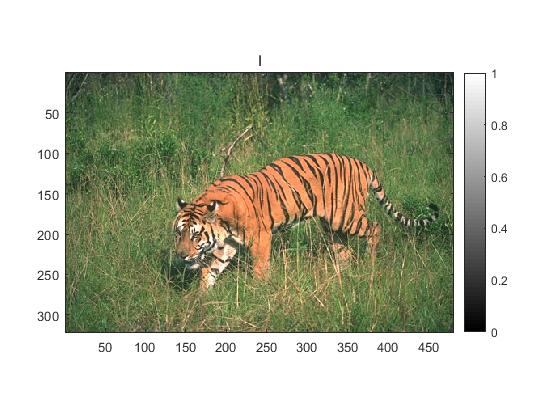

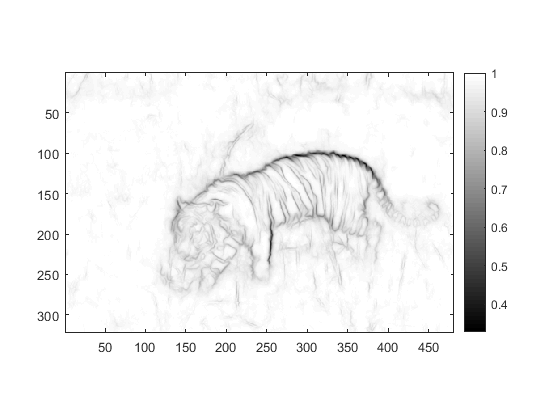

figure(1); im(I); figure(2); im(1-E);

myimage=(1-E);
%save('PigSE.mat','myimage');
save('TigerSE.mat','myimage');